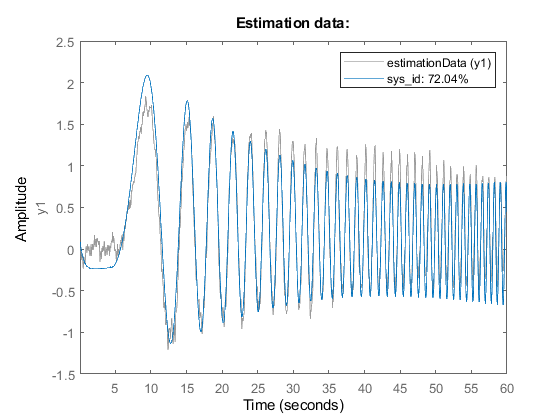

% Create object for time-series data
estimationData = iddata(y,u,0.04);

% Estimate state-space model
sys_id = ssest(estimationData,4);

% Display results
compare(estimationData,sys_id);
clear estimationData;
title('Estimation data:');

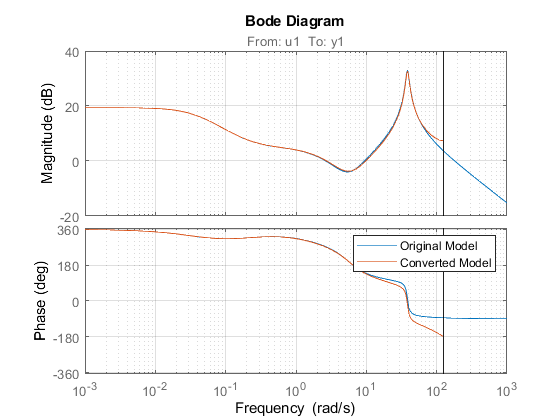

% Convert model from continuous to discrete time
sys_d = c2d(sys_id,0.025);

% Visualize the results
bodeplot(sys_id,sys_d);
legend('Original Model','Converted Model');
grid on;

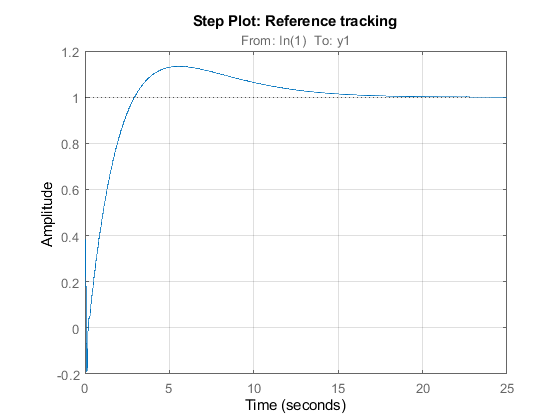

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc = 2/3.02854;

% PID tuning algorithm for linear plant model
[C,pidInfo] = pidtune(sys_d,'PID',wc);

% Clear Temporary Variables
clear wc

% Get desired loop response
Response = getPIDLoopResponse(C,sys_d,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Clear Temporary Variables
clear Response